d1 = abs(100+2150*(randn(6000,1))+10*(200-rand(6000,1)))+1500;
display(['Mean for Data1 : ' num2str(mean(d1))])

Mean for Data1 : 3985.067


display(['SD for Data1 : ' num2str(std(d1))])

SD for Data1 : 1696.6601



d2 = abs(12800+600*(rand(6000,1)+rand(6000,1)));
display(['Mean for Data2 : ' num2str(mean(d2))])

Mean for Data2 : 13396.329


display(['SD for Data2 : ' num2str(std(d2))])

SD for Data2 : 246.5551


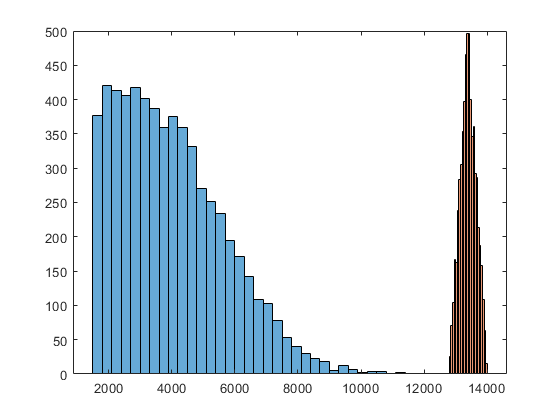


clf
histogram(d1)
hold on 
histogram(d2)

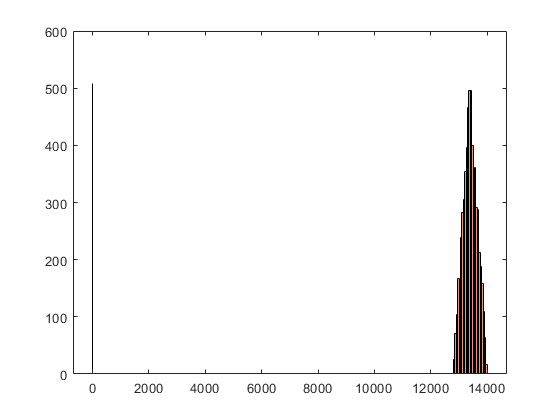



d1 = log(d1);
clf
histogram(d1)
hold on 
histogram(d2)




st1 = my_standardize(d1);st2 = my_standardize(d2);

table([mean(st1);mean(st2)] , [min(st1);min(st2)], ...
    [std(st1);std(st2)], [range(st1);range(st2)], ...
    'RowNames',{'Standardized Data 1','Standardized Data 2'}, ...
    'VariableNames',{'Mean','Min','SD','Range'})

ans = 2×4 table
                            Mean     Min    SD    Range 
                           ______    ___    __    ______

    Standardized Data 1    3.0433     1     1     4.6326
    Standardized Data 2    3.4018     1     1     4.8113


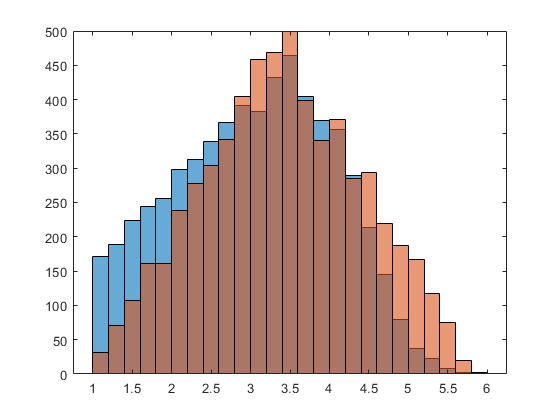


clf
histogram(st1)
hold on 
histogram(st2)


% clf
% histogram(log(st1))
% hold on 
% histogram(st2)

function standard = my_standardize(col)
% 1st one
    standard = ( col-min(col) ) / ( std(col) ) + 1;   

% 2nd way
    standard = ( col-mean(col) ) / ( std(col) );   
    standard = standard + abs(min(standard))+1;

% 3rd approach    
%     standard = ( col-0 ) / ( std(col) );

%     standard = ( col-mean(col) ) / ( std(col) );
end